# Aula 8 - Compensadores em Cascata

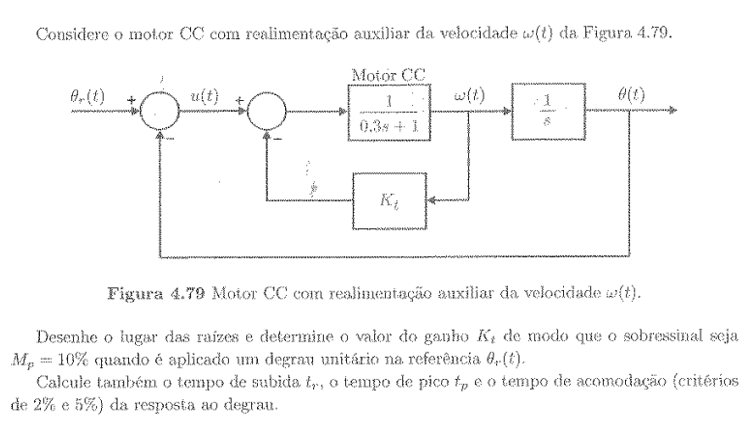

1º) Diagrama de Blocos equivalente:

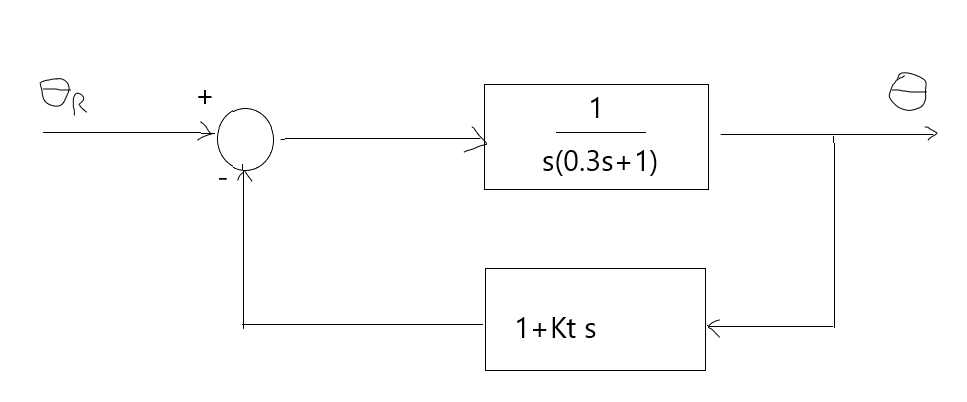

2º) Reorganizar a equação característica para que $K_t$ apenas multiplique:


$$GH=\frac{1+K_ts}{s(0.3s+1)}$$


Eq característica


$$1+GH=0$$



$$1+\frac{1+K_ts}{s(0.3s+1)}=0$$



$$0.3s^2+s+1+K_ts=0$$



$$1+\frac{K_ts}{0.3s^2+s+1}=0$$


$1+GH'=0$, onde $GH'=\frac{K_ts}{0.3s^2+s+1}$

3º) Traçar o LR para $GH'$:

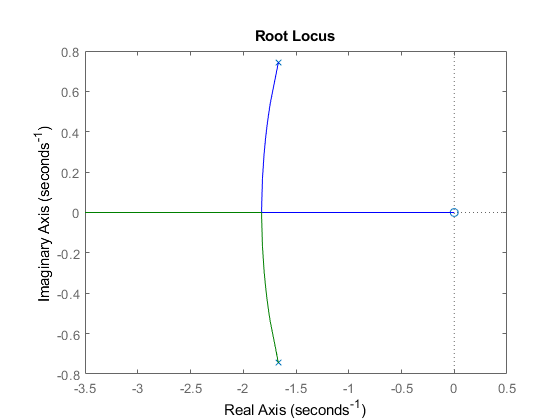

GH=tf([1,0],[0.3,1,1]);
rlocus(GH)

4º) Achar o $K_t$ pela FT de malha fechada:

syms s Kt
G=1/(0.3*s^2+s);
H=1+Kt*s;
FTMF=G/(1+G*H);
FTMF=simplify(FTMF)

$$FTMF = \frac{10}{10\,s+10\,\mathrm{Kt}\,s+3\,s^{2}+10}$$


$$\frac{\theta}{\theta_R}=\frac{\frac{1}{0.3}}{s^2+\frac{(1+K_t)s}{0.3}+\frac{1}{0.3}}$$



$$\omega_n=\sqrt{\frac{1}{0.3}}$$



$$Mp=10%=0.1$$
   
$$\rightarrow$$
    
$$\zeta=-0.353$$


$\frac{(1+K_t)}{0.3}=2\omega_n\zeta$  $\rightarrow$   $K_t=-0.353$, a ideia foi boa, mas ganho negativo não é razoável.

## Solução do Tannuri


$$\frac{\theta}{\theta_R}=\frac{1}{0.3s^2+(1+K_t)s+1}$$


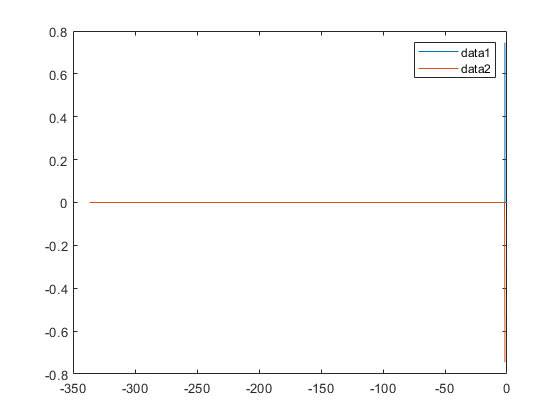

k=0:0.1:100;
delta=(1+k).^2-4*0.3*1;
s1=(-(1+k)+sqrt(delta))/0.6;
s2=(-(1+k)-sqrt(delta))/0.6;
plot(real(s1),imag(s1),real(s2),imag(s2))
legend()

zeta_max=max(imag(s1))

zeta_max = 0.7454